clear;

% 配置
config;
%-----------------------------
% 产生信号
source;
tag;
global y_sig;
y_sig = y_source .* y_tag;

global Length;
global Width;

## 房间内的随机点


N_inside = 8;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);

% 计算三个距离
[d1, d2, d3] = xy2d(x, y);

single_run(d1, d2, d3, false, 'inside');

## 房间外的随机点

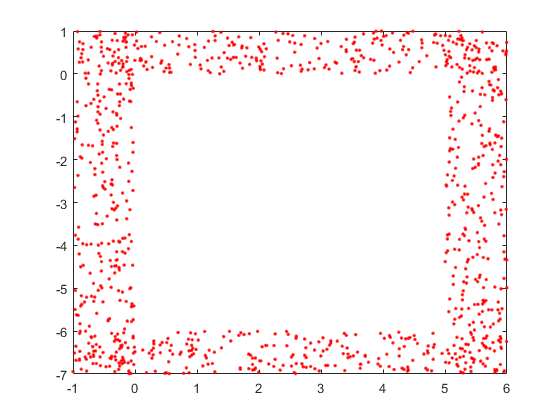


N_outside = 25;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
% TODO: bugfix --- 点都集中在四个角落了，需要分散到边边上
figure; plot(x0,y0,'r.');


% 计算三个距离
[d1_0, d2_0, d3_0] = xy2d(x0, y0);
single_run(d1_0, d2_0, d3_0, false, 'outside');


% 保存样本点
filename = '.\DataSet\sample.mat'
save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理


global block_Nx;
global block_Ny;
% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: N_outside
    preproc('o_sig_rx', i, false, 'outside');
end